%segment data based on peaks

clear;
clc;

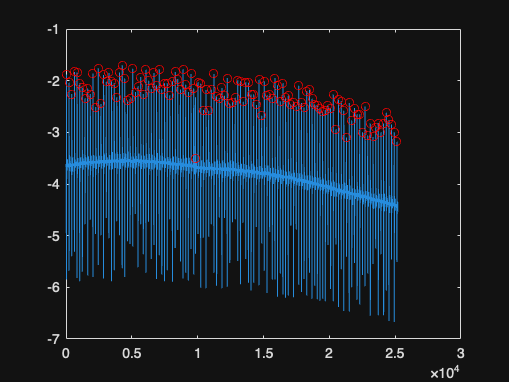

ii = 1;
number =int2str(ii);
% fname = ['Perturb_Data_Sim/SimFail_Full_Ch',number,'.csv'];
fname ='Perturb_Data_Sim/SimFail_Full_Ch1.csv'; % file name for the csv file to segment

labels = categorical(["Fail","Working"]); % labels for the data

F= readmatrix(fname); % read the csv file as matlab matrix

% F= F(600:end,:); % commenting this cuz using pre-cleaned data 
[pks,loc] = findpeaks(F(:,1), 'MinPeakHeight',-6.0,'MinPeakDistance',150); %define peak parameter here, the peaks are found on 1st column

% Visualize peaks on the first column of the data
plot(F(:,1))
hold on; % Retain current plot
plot(loc, pks, 'ro'); % Plot peaks on the existing graph
hold off; % Release the plot hold

%get slices
window = -20 : 139; % start 20 samples before the first peak and stop at 139th sample after first peak (assumption:- inflation peak >= def peak)
num_locs = length (loc); % number of peaks found
win_len = length(window); % length of window

slices = zeros(num_locs,win_len,size(F,2)); % pre -allocating for better speed

% following loop validates if the slicing indices are valid and accordingly slices the F matrix 
for i = 1:num_locs
    start_idx = loc(i) + window;

    valid_idx = start_idx >=1 & start_idx<= size(F,1);
    
    temp = zeros (win_len,size(F,2));
    temp(valid_idx,:) = F(start_idx(valid_idx), :); % Extract the slice from F

    slices(i,:,:) = temp;
end

%set the matrix to cell to add label
data = slices;
chunks = cell(num_locs,7);
for i = 1: num_locs
    for j =1:6
        chunks{i,j}=data(i,:,j)';
    end
    chunks{i,7} = labels(2); % Store the 7th slice in the chunks cell array, label is added here

end

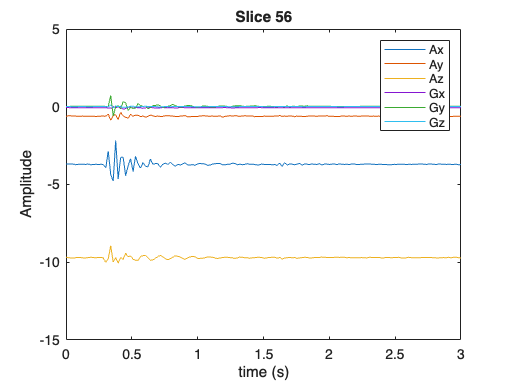

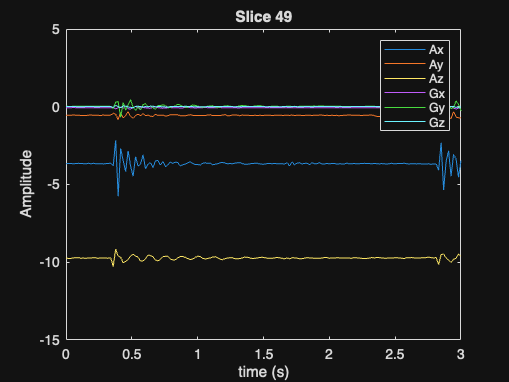

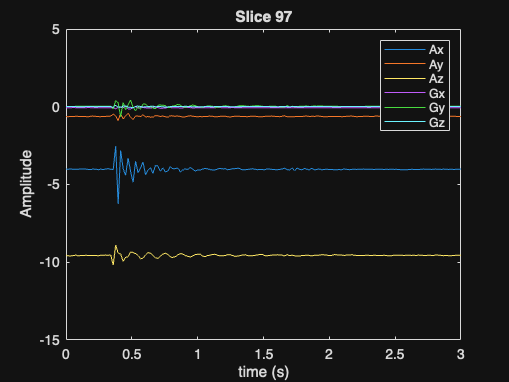

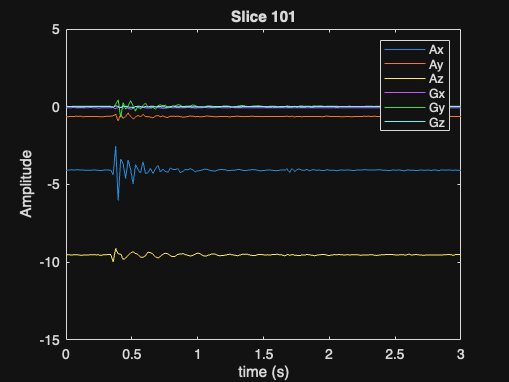

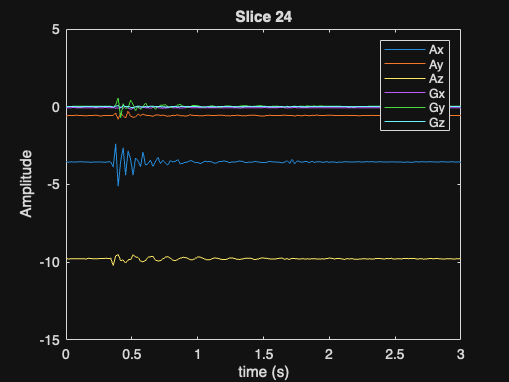

%visualize random slices for sanity check
randomIndices = randi(num_locs, 1, 5); % Select 5 random slices

for j = 1:length(randomIndices)
    figure; % Create a new figure for visualization
    t= linspace(0,3,160);
    % t= t/60;
    plot(t,cell2mat(chunks(randomIndices(j),1:6))); % Plot the selected slice
    legend('Ax', 'Ay', 'Az', 'Gx', 'Gy', 'Gz')
    % xlim([0 150])
    ylim([-15.0 5.0])
    xlabel('time (s)');
    ylabel('Amplitude');
    title(['Slice ' num2str(randomIndices(j))]);
end

% Convert chunks to a table for better data handling
dataTable = cell2table(chunks, 'VariableNames', {'Ax', 'Ay', 'Az', 'Gx', 'Gy', 'Gz', 'label'});

% sname = sprintf('Perturb_Data_Sim/SimFail_Full_Ch %d.mat',ii);
sname = 'Perturb_Data_Sim/SimFail_Perturb_4Working__When_3and5_are_disconnected.mat'; % this is the place where the table containing data will be stored
save(sname, 'dataTable') % comment this line if do not want to save

Error using save
Cannot create 'SimFail_Perturb_4Working__When_3and5_are_disconnected.mat' because 'Perturb_Data_Sim' does not exist.